# PBMRAC Development

This live script tackles the development of the PBMRAC controller for a simplied model containing only the position dynamics. First, we will develop and check the baseline model with its controller. Then, the PBMRAC architecture will be introduced and the "adaptive equilibrium" checked as an initial verification. Afterwards, the representative trajectory used in task 2 will be used to tune the adaptive controller. Finally, the model's response will be tested under some given external dynamic disturbance. 

addpath("Models and Auxiliary Functions\")

## Baseline Model Definition:

Begin by defining a baseline model and testing its implementation by checking that it meets the performance requirements.  

%Set initial conditions:
p_i_0=[0;0;0];
v_i_0=[0;0;0];

%Nominal system: 
Lambda_tilde=eye(3,3);
a_e_tilde=[0;0;0];

%Tune position controller: 
%Performance Goals: 
omega_n_p=1.75; %[rad/s]
zeta_p=0.8;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

Now let's test the step response in all three directions. 

#### Case 1: step in x direction

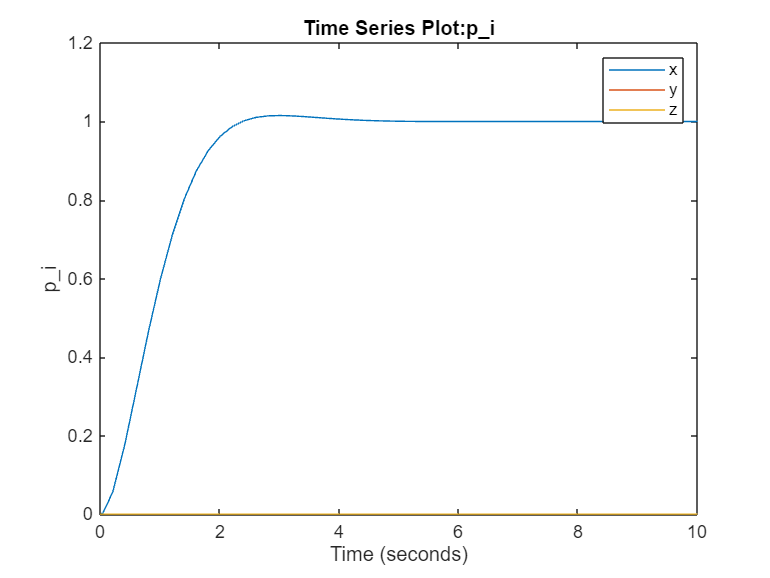

%Step in the x direction: 
dir=[1;0;0];

simout=sim("PBMRAC_Baseline_Model.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_i)
legend('x','y','z')

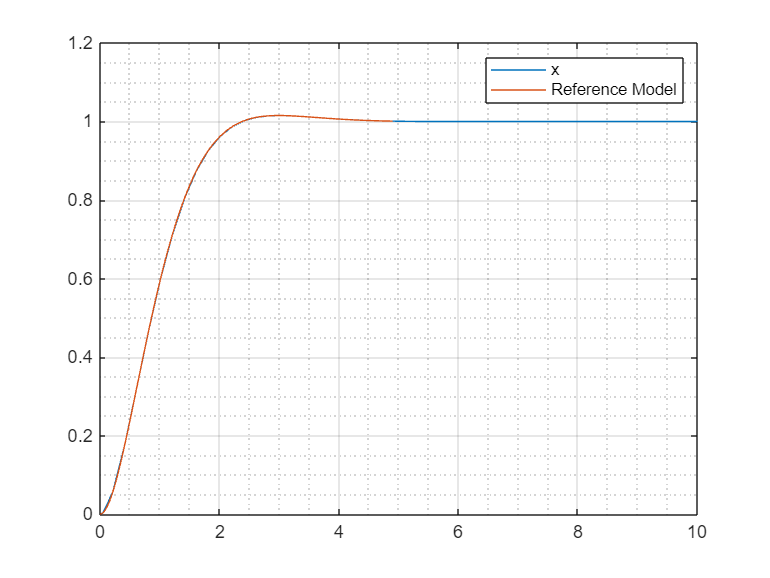


x_data=nan(size(simout.p_i.time));
for i=1:length(simout.p_i.time)
    x_data(i)=simout.p_i.data(1,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[x_ref,t_ref]=step(G);

figure
clf
plot(simout.p_i.time,x_data,'DisplayName','x')
hold on
plot(t_ref,x_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()

#### Case 2: step in y direction

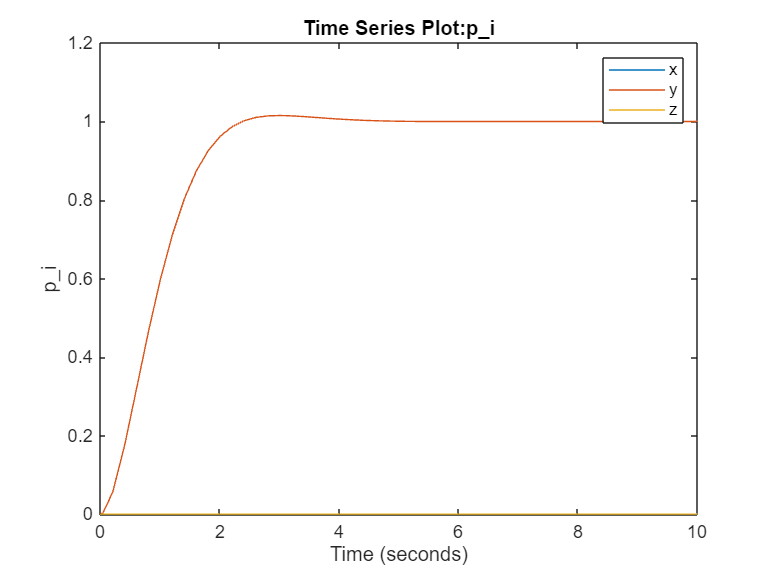

%Step in the y direction: 
dir=[0;1;0];

simout=sim("PBMRAC_Baseline_Model.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_i)
legend('x','y','z')

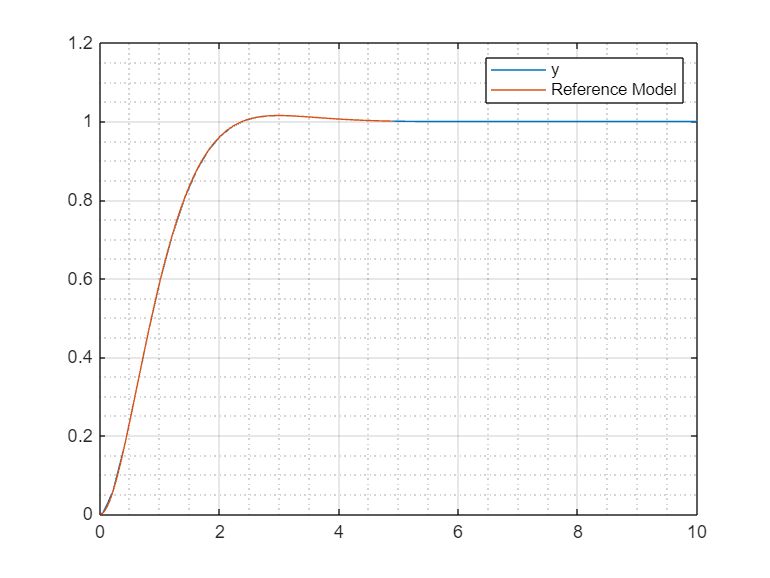


y_data=nan(size(simout.p_i.time));
for i=1:length(simout.p_i.time)
    y_data(i)=simout.p_i.data(2,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[x_ref,t_ref]=step(G);

figure
clf
plot(simout.p_i.time,y_data,'DisplayName','y')
hold on
plot(t_ref,x_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()

#### Case 3: step in z direction

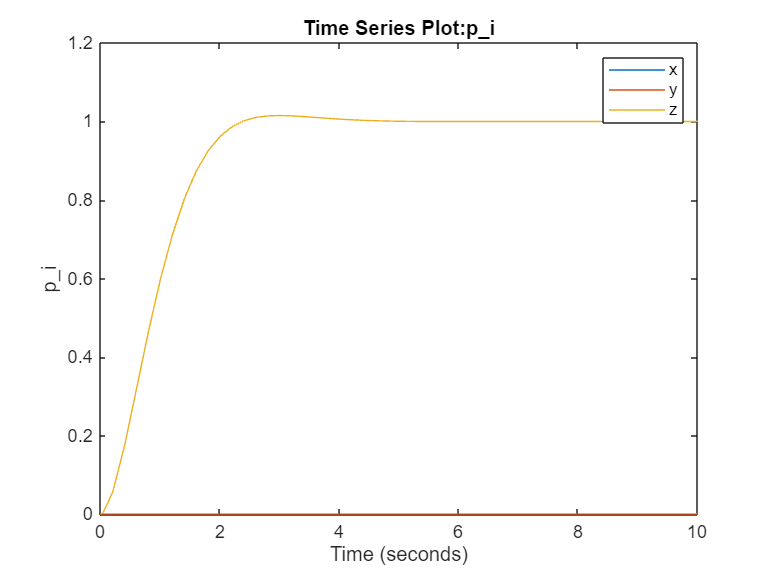

%Step in the z direction: 
dir=[0;0;1];

simout=sim("PBMRAC_Baseline_Model.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_i)
legend('x','y','z')

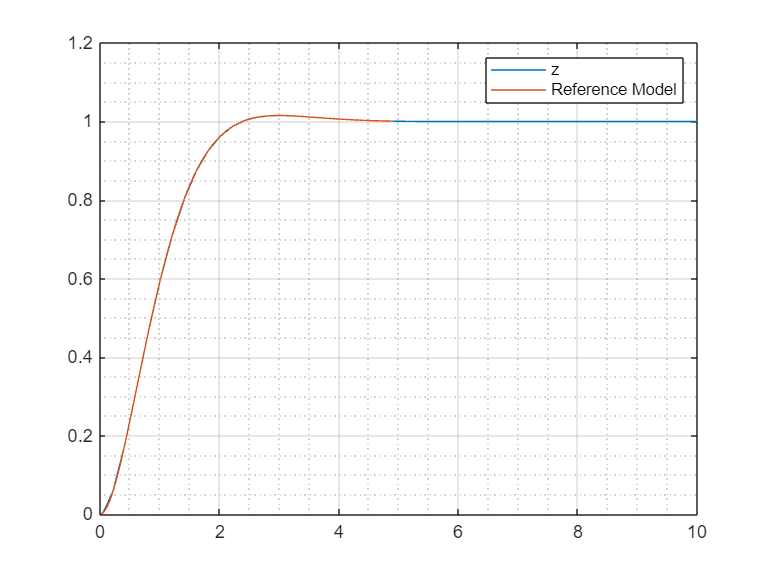


z_data=nan(size(simout.p_i.time));
for i=1:length(simout.p_i.time)
    z_data(i)=simout.p_i.data(3,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[x_ref,t_ref]=step(G);

figure
clf
plot(simout.p_i.time,z_data,'DisplayName','z')
hold on
plot(t_ref,x_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()

Excellent results all along, so we can consider the initial implementation validated. Now it's time to add the adaptive controller. 

## Adaptive Augmentation: 

Now we introduce adaptive augmentation to the model. The first test of the implementation will be to check the "adaptive equilibrium". In essence, if we initialize the adaptive law with the correct values for the parameters and in the nominal case, the system response should be unaffected. First, let's define all the elements necessary for the adaptive controller: 

%For predictor dynamics: 
A_p=[zeros(3,3),eye(3,3);zeros(3,3),zeros(3,3)];
B_p=[zeros(3,3);eye(3,3)];
B_pT=B_p';

%Initialize gains (to be tuned later on): 
L=eye(6,6);
Gamma_a=eye(6,6);

#### Case 2.1: nominal case with adaptive control

Let's simulate only the x step, if it works all of them should. 

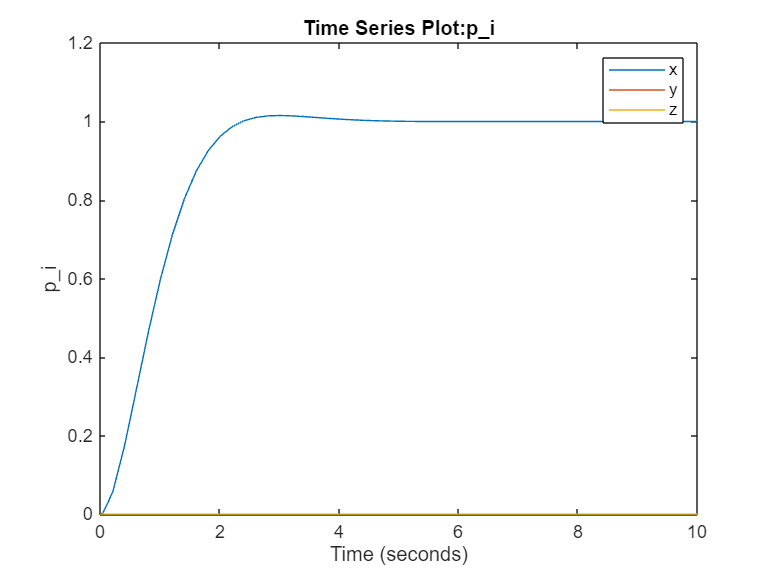

%Initialize adaptive laws: 
lambda_hat_0=[1;1;1];
a_e_hat_0=[0;0;0];
omega_a_hat_0=[lambda_hat_0;a_e_hat_0];

%Initialize predictor: 
p_i_hat_0=p_i_0;
v_i_hat_0=v_i_0;
x_hat_0=[p_i_hat_0;v_i_hat_0];

%Simulate x step:
%Step in the x direction: 
dir=[1;0;0];

simout=sim("PBMRAC_Augmented_Model.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_i)
legend('x','y','z')


x_data=nan(size(simout.p_i.time));
for i=1:length(simout.p_i.time)
    x_data(i)=simout.p_i.data(1,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[x_ref,t_ref]=step(G);

figure
clf
plot(simout.p_i.time,x_data,'DisplayName','x')
hold on
plot(t_ref,x_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()

As expected, the dynamics of the nominal system are unaffected by the existence of the adaptive controller if it is initialized with the correct values. Let's now try one step further, try a non-nominal system but with the exact initialization.

#### Case 2.2: non-nominal system with exactly initialized adaptive augmentation

%Non-Nominal system: 
Lambda_tilde=0.8*eye(3,3);
a_e_tilde=[0;0;-9.81]; %[m/s^2]

%Initialize adaptive laws: 
lambda_hat_0=diag(Lambda_tilde);
a_e_hat_0=a_e_tilde;
omega_a_hat_0=[lambda_hat_0;a_e_hat_0];

%Initialize predictor: 
p_i_hat_0=p_i_0;
v_i_hat_0=v_i_0;
x_hat_0=[p_i_hat_0;v_i_hat_0];

%Step in the y direction: 
dir=[0;1;0];

simout=sim("PBMRAC_Augmented_Model.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_i)
legend('x','y','z')


y_data=nan(size(simout.p_i.time));
for i=1:length(simout.p_i.time)
    y_data(i)=simout.p_i.data(2,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[x_ref,t_ref]=step(G);

figure
clf
plot(simout.p_i.time,y_data,'DisplayName','y')
hold on
plot(t_ref,x_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()

As expected, the system retains its ideal performance from the start.

#### Case 2.3: non-nominal case with non-exactly initialized adaptive controller

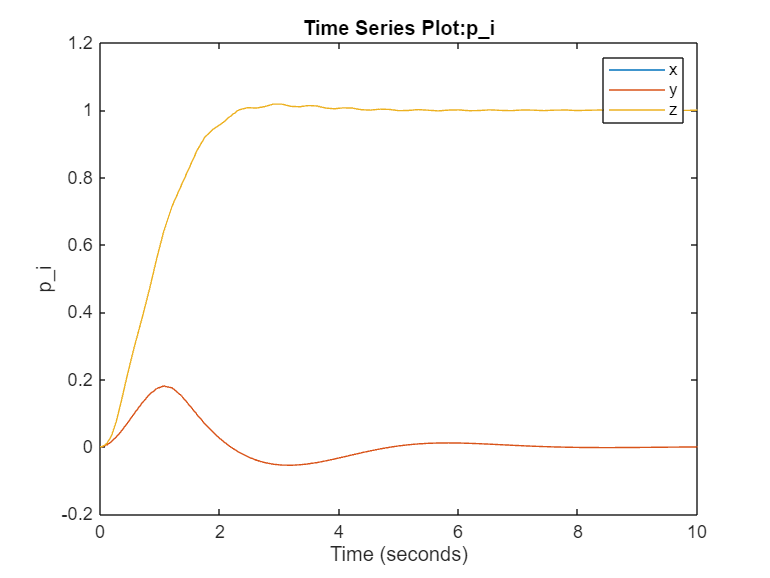

%Non-Nominal system: 
Lambda_tilde=0.8*eye(3,3);
g=9.81; %[m/s^2]
a_e_tilde=[0;0;-g]+0.1*g*ones(3,1); %[m/s^2]

%Initialize adaptive laws: 
lambda_hat_0=ones(3,1);
a_e_hat_0=[0;0;-g];
omega_a_hat_0=[lambda_hat_0;a_e_hat_0];

%Initialize predictor: 
p_i_hat_0=p_i_0;
v_i_hat_0=v_i_0;
x_hat_0=[p_i_hat_0;v_i_hat_0];

%Step in the z direction: 
dir=[0;0;1];

simout=sim("PBMRAC_Augmented_Model.slx");

%Plot system response: 
%Plot position:
figure
clf
plot(simout.p_i)
legend('x','y','z')

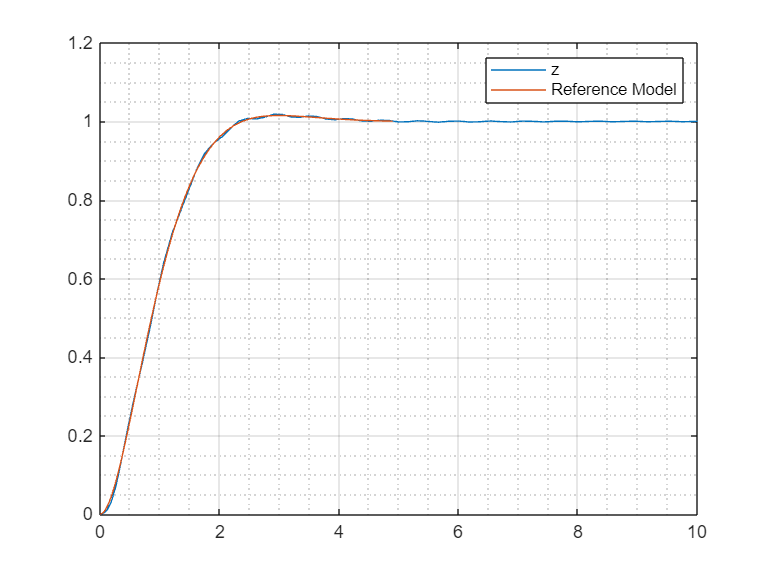


z_data=nan(size(simout.p_i.time));
for i=1:length(simout.p_i.time)
    z_data(i)=simout.p_i.data(3,1,i);
end

%Reference model response: 
s=tf('s');
G=omega_n_p^2/(s^2+2*zeta_p*omega_n_p*s+omega_n_p^2);
[x_ref,t_ref]=step(G);

figure
clf
plot(simout.p_i.time,z_data,'DisplayName','z')
hold on
plot(t_ref,x_ref,'DisplayName','Reference Model')
grid on 
grid minor
legend()